# LIF Neuron With Dynamic Refractory Period

vth2 = zeros(size(tvec)); % Vector for the threshold voltage
vth2(1) = Vth;            % Initialize the threshold voltage to the resting potential
vth_max = 0.2;            % Maximum threshold voltage (cap voltage at 200 mV)
vtau = 0.001;             % Time constant for refractory period (in seconds)
twait2 = vtau/dt;         % Number of time steps to wait during refractory period

% New firing rate, membrane voltage and mean Vm vectors

fr_2 = zeros(size(Iapp));  % Firing rate vector
Vvec2 = zeros(size(tvec)); % Membrane voltage vector
Vvec2(1) = El;             % Initialize the membrane voltage to the resting potential

mean_V2 = zeros(size(Iapp));   % Mean membrane voltage vector
pltV2 = zeros(2,length(tvec)); % Hold two voltage traces for 220pA and 600pA


## Firing Simulation

% Initialize index loop 
for b = 1:length(Iapp)
    spiket2 = zeros(size(tvec)); % Spike train vector
        for i = 2:length(tvec)

        % Calculate the change in membrane voltage
        dVdt = ((El - Vvec2(i-1))/Rm + Iapp(b))/Cm;
        Vvec2(i) = Vvec2(i-1) + dVdt*dt; % Update membrane voltage

        % Calculate the change in threshold voltage
        dVthdt = (Vth - vth2(i-1))/vtau;
        vth2(i) = vth2(i-1) + dVthdt*dt;

        % If a spike occurred at the previous time step
        if spiket2(i) == -1
            Vvec2(i) = Vr; % Reset membrane voltage to the resting potential
        end

        % If the membrane voltage crosses the threshold voltage
        if Vvec2(i) > vth2(i)
        Vvec2(i) = Vr;     % Reset membrane voltage to the resting potential
        spiket2(i) = 1;    % Record a spike
        vth2(i) = vth_max; % Increase the threshold voltage to the cap voltage

        % Refractory period
            for k = 1:twait2
        spiket2(i + k) = -1; % Set the spike train vector to -1 during the refractory period
            end
        end
        end

    % Update the membrane voltage trace for spikes
    spikecount2 = find(spiket2 == 1);
    for ind = spikecount2
    Vvec2(ind) = Vpeak;
    end

    % Calculate the mean membrane voltage and firing rate
    mean_V2(b) = mean(Vvec2);
    fr_2(b) = length(spikecount2)/tmax;
    if b == 13
    pltV2(1,:) = Vvec2;
    elseif b == 51
    pltV2(2,:) = Vvec2;
    end
end

## Plot Voltage Traces at 220pA and 600pA 

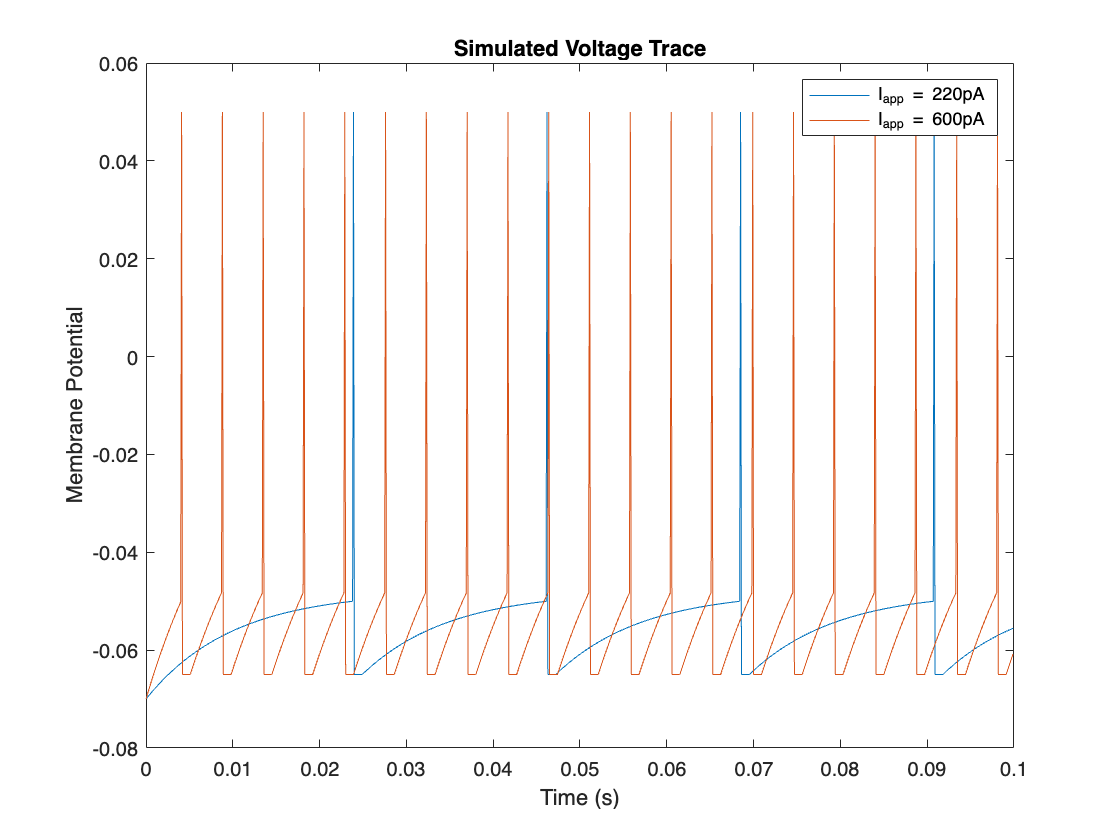


figure;
plot(tvec(:,1:1000), pltV2(1,1:1000), tvec(:,1:1000), pltV2(2,1:1000));
title('Simulated Voltage Trace');
xlabel('Time (s)');
ylabel('Membrane Potential');
legend('I_{app} = 220pA', 'I_{app} = 600pA');